omega1(:,2) = omega(:,2)/.002/4

omega1 =      0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0
     0     0


omega1(:,1) = omega(:,1)

omega1 =          0         0
    0.0020         0
    0.0040         0
    0.0060         0
    0.0080         0
    0.0100         0
    0.0120         0
    0.0140         0
    0.0160         0
    0.0180         0


plot(omega1(:,1),omega1(:,2))
hold on

%%Steady state value Oscillates between
%0.187145656122048
%0.190213617697820
SSV = ((.190213617697820-.187145656122048)/2 + .187145656122048)/.002/4

SSV = 23.5850

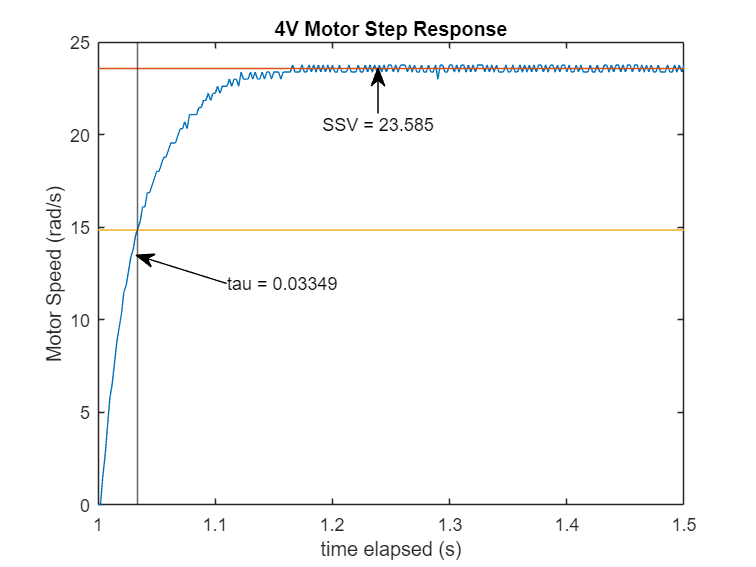

syms y
fplot(SSV)
fplot(SSV*0.63)


hold off
xlim([1,1.5])
ylim([0,25])
x = [0.5 0.5];
y = [0.8 .88];
annotation('textarrow',x,y,'String','SSV = ' + string(round(SSV,3)))
x = [0.3 0.18];
y = [0.5 .55];
annotation('textarrow',x,y,'String','tau = 0.03349')
x = [0.55 0.29];
y = [0.4 .5];
% annotation('textarrow',x,y,'String','t_{tau} = ' + string(round(Ttau, 3)))
xlabel("time elapsed (s)")
ylabel("Motor Speed (rad/s)")
title("4V Motor Step Response")
xline(1.03349)
hold off


k = SSV/4

k = 5.8962

tau = .03349

tau = 0.0335



s = tf('s');
model = k/(tau*s+1);
o = omega1(:,2);
plot(omega1(501:751,1),omega1(501:751,2) )
hold on
sys = tf(4,[1 2 10]);
t = 1:0.002:1.5;
y = 4*step(model,t);
size(y)

ans =    251     1


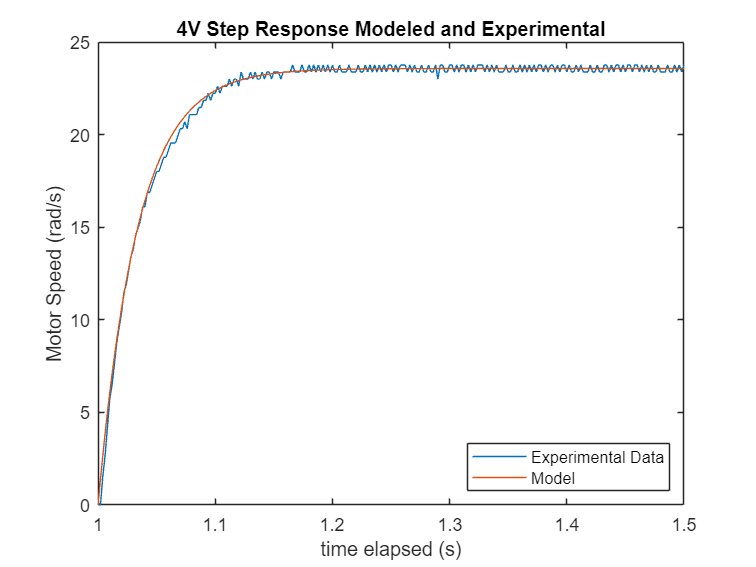

plot(omega1(501:751,1),y)
xlabel("time elapsed (s)")
ylabel("Motor Speed (rad/s)")
title("4V Step Response Modeled and Experimental")
legend("Experimental Data", "Model", "Location","southeast")
hold off

T = 0.002;
pulse = c2d(model,T,'zoh')

pulse =
 
   0.3418
  ---------
  z - 0.942
 
Sample time: 0.002 seconds
Discrete-time transfer function.
Model Properties


z = tf("z", 0.002);
pulse2 = k*(1-exp(-T/tau))/(z-exp(-T/tau))

pulse2 =
 
   0.3418
  ---------
  z - 0.942
 
Sample time: 0.002 seconds
Discrete-time transfer function.
Model Properties


plot(out.cont(:,1), out.cont(:,2))

Unable to resolve the name 'out.cont'.

hold on
stairs(out.disc(:,1), out.disc(:,2))
xlim([0.9,1.5])
ylim([0,24])
legend("Continuous Model", "Discrete Model", "Location", "southeast")
xlabel("time elapsed (s)")
ylabel("Motor Speed (rad/s)")
title("Simulink Model Results")
hold off